Cd0=0.017       %0.014-0.020

Cd0 = 0.0170

AR=8            %Assumed 

AR = 8

e=1.78*(1-0.045*AR^0.68)-0.64

e = 0.8106

k=1/(pi*AR*e)   

k = 0.0491

Clmax=1.5       %Assumed: 1.2-1.6

Clmax = 1.5000

mu=0.5

mu = 0.5000

Cd_0LG=0.009    %0.006-0.012

Cd_0LG = 0.0090

Cd_0HLDto=0.005 %0.003-0.008

Cd_0HLDto = 0.0050

Cl_c=0.4        %0.3-0.5

Cl_c = 0.4000

Cl_flapTo=0.5   %0.3-0.8

Cl_flapTo = 0.5000


Vs=20

Vs = 20

Vmax=40        %1.2 Vcruise- Vcruise was assumed to be 34m/s(185/1.25 km/hr)

Vmax = 40

V_r=25

V_r = 25

V_to=1.2*Vs

V_to = 24

ROC=2           %3-10

ROC = 2

ROC_ceiling=0.5

ROC_ceiling = 0.5000

LbyD_max=15     %Assumed

LbyD_max = 15

W_To=160*9.8

W_To = 1568

Sto=200

Sto = 200


n=150

n = 150

row=1.225

row = 1.2250

ceiling=500

ceiling = 500

g0=9.81

g0 = 9.8100

g=9.81

g = 9.8100

sigma=(1-6.873*10^(-6)*ceiling)^4.26

sigma = 0.9854

efficiency=0.7

efficiency = 0.7000

%stall speed
WbyS_Vs=0.5*row*(Vs^2)*Clmax*ones(1,20);
WbyPsl_Vs=linspace(0,0.6,20)

WbyPsl_Vs =          0    0.0316    0.0632    0.0947    0.1263    0.1579    0.1895    0.2211    0.2526    0.2842    0.3158    0.3474    0.3789    0.4105    0.4421    0.4737    0.5053    0.5368    0.5684    0.6000


%Vmax 
WbyS_Vmax=linspace(60,450,n);
WbyPsl_Vmax=sigma*efficiency./((row*(Vmax^3)*Cd0*0.5)./WbyS_Vmax+2*k*WbyS_Vmax/(row*sigma*Vmax))  %(row*(Vmax^3)*Cd0*0.5)./WbyS_Vmax

WbyPsl_Vmax =     0.0614    0.0641    0.0667    0.0693    0.0719    0.0744    0.0770    0.0796    0.0821    0.0847    0.0872    0.0898    0.0923    0.0948    0.0973    0.0998    0.1022    0.1047    0.1071    0.1096    0.1120    0.1144    0.1168    0.1192    0.1215    0.1239    0.1262    0.1286    0.1309    0.1332    0.1355    0.1377    0.1400    0.1422    0.1444    0.1467    0.1488    0.1510    0.1532    0.1553    0.1575    0.1596    0.1617    0.1637    0.1658    0.1678    0.1699    0.1719    0.1739    0.1759


%ROC 
WbyS_roc=linspace(60,450,n);
WbyPsl_roc=1./(ROC/efficiency+sqrt(2*WbyS_roc/(sigma*row*sqrt(3*Cd0/k)))*1.155/(LbyD_max*efficiency))

WbyPsl_roc =     0.2536    0.2521    0.2506    0.2492    0.2479    0.2465    0.2453    0.2440    0.2428    0.2416    0.2404    0.2393    0.2382    0.2371    0.2361    0.2351    0.2340    0.2331    0.2321    0.2312    0.2302    0.2293    0.2284    0.2275    0.2267    0.2258    0.2250    0.2242    0.2234    0.2226    0.2218    0.2211    0.2203    0.2196    0.2189    0.2182    0.2174    0.2168    0.2161    0.2154    0.2147    0.2141    0.2134    0.2128    0.2122    0.2115    0.2109    0.2103    0.2097    0.2091


%take off distance
WbyS_Sto=linspace(60,450,n);
Cl_To=Cl_c+Cl_flapTo

Cl_To = 0.9000

Cd_0To=Cd0+Cd_0LG+Cd_0HLDto

Cd_0To = 0.0310

Cd_To=Cd_0To+k*Cl_To^2

Cd_To = 0.0708

Cl_r=2*WbyS_Sto/(row*V_r^2)

Cl_r =     0.1567    0.1636    0.1704    0.1772    0.1841    0.1909    0.1978    0.2046    0.2114    0.2183    0.2251    0.2319    0.2388    0.2456    0.2525    0.2593    0.2661    0.2730    0.2798    0.2866    0.2935    0.3003    0.3072    0.3140    0.3208    0.3277    0.3345    0.3413    0.3482    0.3550    0.3619    0.3687    0.3755    0.3824    0.3892    0.3960    0.4029    0.4097    0.4166    0.4234    0.4302    0.4371    0.4439    0.4507    0.4576    0.4644    0.4713    0.4781    0.4849    0.4918


Cd_G=Cd_To-mu*Cl_To

Cd_G = -0.3792

WbyPsl_Sto=(efficiency/V_to)./((mu-(mu+Cd_G./Cl_r).*exp(0.6*row*sigma*g*Cd_G*Sto./WbyS_Sto))./(1-exp(0.6*row*sigma*g*Cd_G*Sto./WbyS_Sto)))

WbyPsl_Sto =     0.0583    0.0583    0.0583    0.0582    0.0582    0.0582    0.0582    0.0581    0.0581    0.0580    0.0580    0.0579    0.0578    0.0578    0.0577    0.0576    0.0575    0.0574    0.0573    0.0572    0.0571    0.0570    0.0569    0.0568    0.0566    0.0565    0.0564    0.0563    0.0561    0.0560    0.0559    0.0558    0.0556    0.0555    0.0554    0.0552    0.0551    0.0549    0.0548    0.0547    0.0545    0.0544    0.0543    0.0541    0.0540    0.0539    0.0537    0.0536    0.0535    0.0533


%ceiling
WbyS_ceiling=linspace(60,450,n);
WbyPsl_ceiling=sigma./(ROC_ceiling/efficiency+sqrt(2*WbyS_ceiling/(sigma*row*sqrt(3*Cd0/k)))*1.155/(LbyD_max*efficiency))

WbyPsl_ceiling =     0.5473    0.5403    0.5335    0.5271    0.5210    0.5151    0.5094    0.5040    0.4987    0.4937    0.4888    0.4841    0.4795    0.4751    0.4708    0.4667    0.4627    0.4588    0.4550    0.4513    0.4478    0.4443    0.4409    0.4376    0.4344    0.4313    0.4282    0.4252    0.4223    0.4195    0.4167    0.4140    0.4113    0.4087    0.4062    0.4037    0.4013    0.3989    0.3965    0.3942    0.3920    0.3898    0.3876    0.3855    0.3834    0.3813    0.3793    0.3773    0.3754    0.3735


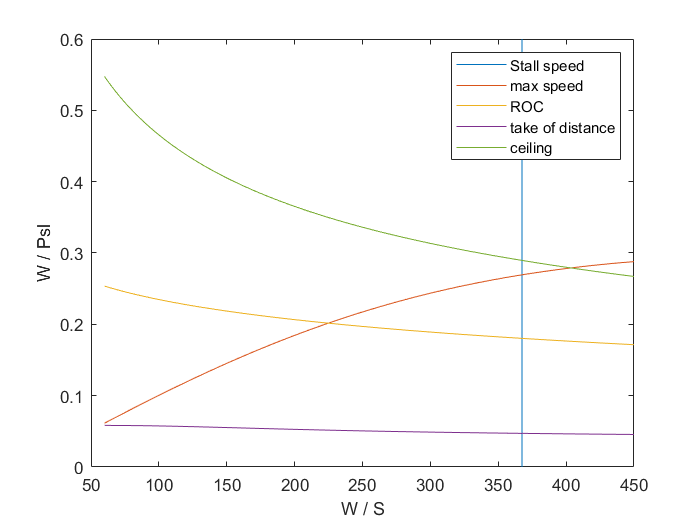

plot(WbyS_Vs,WbyPsl_Vs)
hold on
plot(WbyS_Vmax,WbyPsl_Vmax)
plot(WbyS_roc,WbyPsl_roc)
plot(WbyS_Sto,WbyPsl_Sto)
plot(WbyS_ceiling,WbyPsl_ceiling)
xlabel("W / S")
ylabel("W / Psl")
legend("Stall speed","max speed","ROC","take of distance","ceiling")
hold off